% Load the training data 
data = load("aug4signs_trainingdata_n2.mat");
trainingData = data.trainingData;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

detector = yolov4ObjectDetector("tiny-yolov4-coco");
detector.Network;

% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


classes = {'TrafficSign'};
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MiniBatchSize=16,...
    MaxEpochs=50, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=5, ...
    Plots="training-progress");


*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1          5         00:01:01        0.001         16.238   
      1         10         00:01:37        0.001         9.879    
      2         15         00:02:04        0.001         12.448   
      2         20         00:02:30        0.001         12.843   
      3         25         00:02:50        0.001         7.6106   
      3         30         00:03:14        0.001         9.6222   
      3         35         00:03:36        0.001         7.1926   
      4         40         00:03:57        0.001         7.6663   

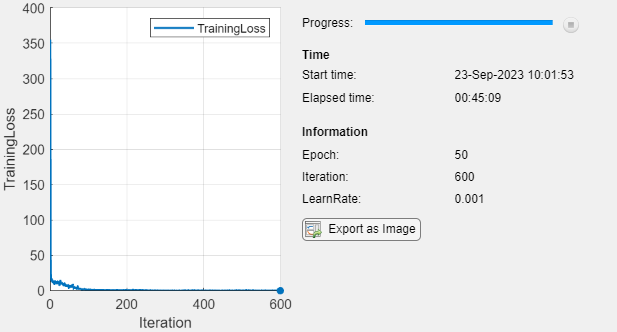

     50         600        00:45:02        0.001        0.042173  

*************************************************************************
Detector training complete.
*************************************************************************



% Train the YOLO v4 network.
trainedDetector_4signs = trainYOLOv4ObjectDetector(ds,detector,options);

save('aug4signs_yolov4_50e_n2.mat','trainedDetector_4signs');


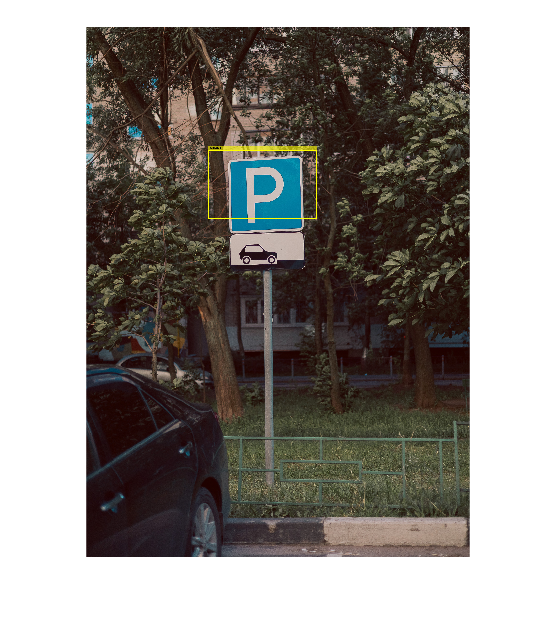

I = imread("C:\Users\Calm\Downloads\testing-signs\parking\parking (2).jpg");

[bboxes, scores, labels] = detect(trainedDetector_4signs,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels,"LineWidth",8,"FontSize",24);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end